% Ask user to select an image
[filename, filepath] = uigetfile({'*.jpg;*.png', 'Image files (*.jpg, *.png)'}, 'Select an image');
if isequal(filename, 0) || isequal(filepath, 0)
    disp('No image selected. Exiting.');
    return;
end

% Read the selected image
imagePath = fullfile(filepath, filename);
inputImage = imread(imagePath);

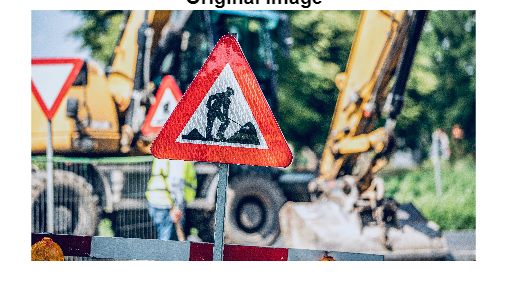


% Display the original image
% figure;
% subplot(1, 3, 1);
imshow(inputImage);
title('Original Image');

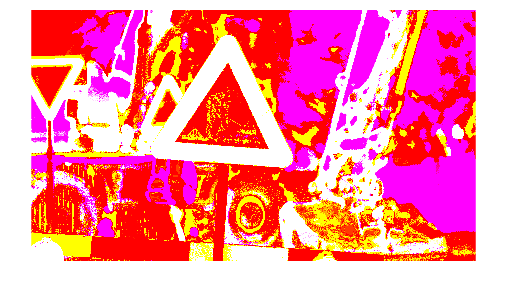


% Convert the image to the LAB color space
labImage = rgb2lab(inputImage);
imshow(labImage)

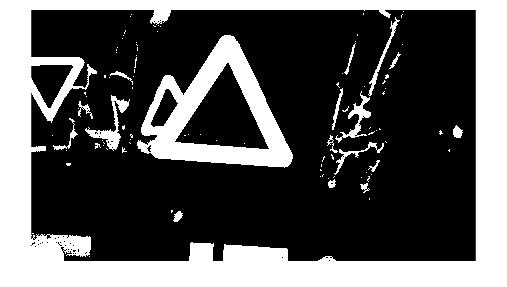


% Extract the "a" channel which represents color differences
aChannel = labImage(:, :, 2);

% Thresholding to segment potential traffic sign regions
binaryImage = aChannel > 10; % Adjust threshold as needed
imshow(binaryImage)

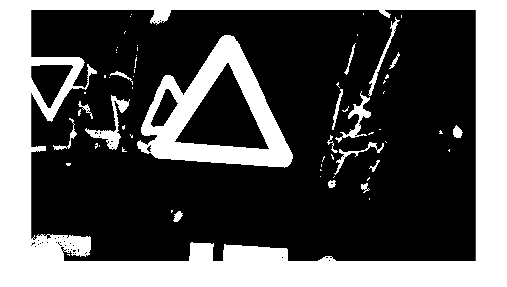


% Remove small noise regions
binaryImage = bwareaopen(binaryImage, 200);
imshow(binaryImage)

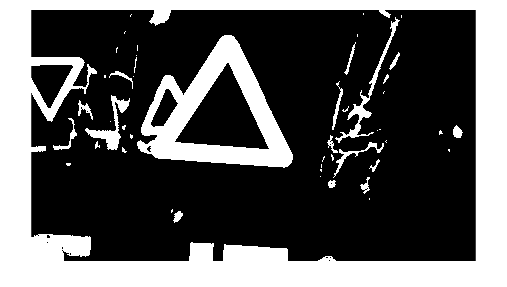


% Perform morphological operations to enhance the regions
se = strel('disk', 5);
binaryImage = imclose(binaryImage, se);
imshow(binaryImage)

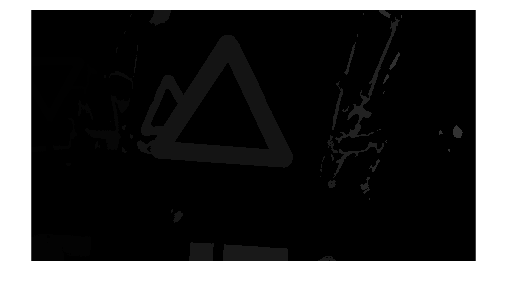



% Identify and label connected components
cc = bwconncomp(binaryImage);
labeledImage = labelmatrix(cc);
imshow(labeledImage)

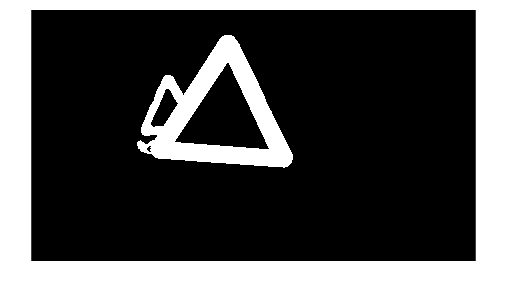


% Calculate the area of each connected component
area = regionprops(cc, 'Area');
areaArray = [area.Area];

% Find the largest connected component (assumed to be the traffic sign)
[~, idx] = max(areaArray);

% Create a mask of the detected traffic sign
trafficSignMask = labeledImage == idx;
imshow(trafficSignMask)


% Get the bounding box of the detected traffic sign
boundingBox = regionprops(trafficSignMask, 'BoundingBox');
bb = boundingBox.BoundingBox;

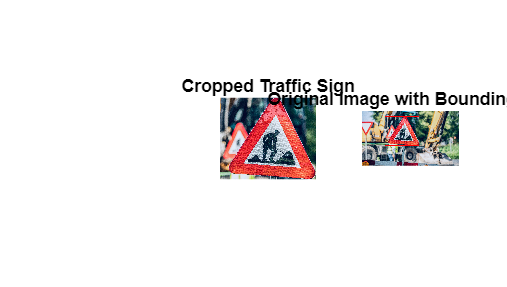


% Add a margin around the bounding box
margin = 5; % Adjust the margin size as needed
expandedBoundingBox = [bb(1) - margin, bb(2) - margin, bb(3) + 2*margin, bb(4) + 2*margin];

% Crop the original image using the expanded bounding box
croppedTrafficSign = imcrop(inputImage, expandedBoundingBox);

% Display the cropped traffic sign
subplot(1, 3, 2);
imshow(croppedTrafficSign);
title('Cropped Traffic Sign');

% Draw the bounding box on the original image
imageWithBoundingBox = insertShape(inputImage, 'Rectangle', bb, 'LineWidth', 2, 'Color', 'red');

% Display the original image with bounding box
subplot(1, 3, 3);
imshow(imageWithBoundingBox);
title('Original Image with Bounding Box');


% Save the cropped traffic sign
outputPath = fullfile(filepath, 'cropped_traffic_sign.png');
% imwrite(croppedTrafficSign, outputPath);
% disp(['Cropped traffic sign saved at: ' outputPath]);
